# Classroom assignments 2 例程

`对模拟信号：`$x_a \left(t\right)=\sin \left(2\pi \ast f_1 \ast t\right)+\cos \left(2\pi \ast f_2 \ast t\right)\;,{\;f}_1 =1\textrm{Hz}\;,{\;f}_2 =2\textrm{Hz}$，

`以采样率`$F_2 =16\textrm{Hz}$ ，`采样`16`点得到数字序列`$x\left(n\right)$`。`

`画出模拟信号、模拟信号采样、数字序列。`

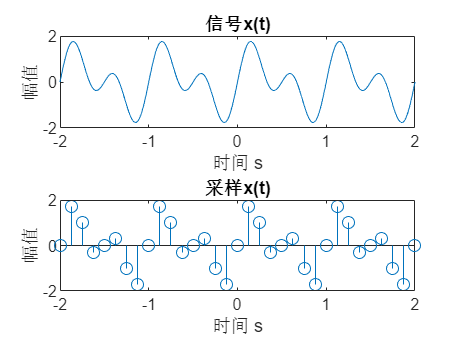

fs = 8; %Hz 
f1 = 1;  %Hz
f2 = 2;  %Hz
dt = 0.001; %仿真步长：0.001s
t = -2:dt:2; %仿真时长：2s

figure(1);
%信号
xt = sin(2*pi*f1*t) + sin(2*pi*f2*t); 
subplot(2,1,1);plot(t,xt);xlim([-2 2]);ylim([-2 2]);
xlabel('时间 s');ylabel('幅值');title('信号x(t)');

%8Hz采样
subplot(2,1,2);
t_sample = -2:1/fs:2;
x_sample = sin(2*pi*f1*t_sample) + sin(2*pi*f2*t_sample);
stem(t_sample,x_sample);
xlabel('时间 s');ylabel('幅值');title('采样x(t)');

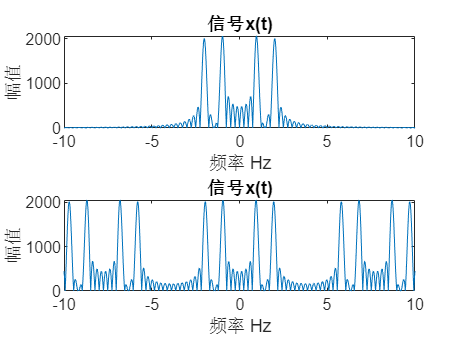

figure(2);
%原始信号FFT
yt = fftshift(fft(xt,1/dt*100));
ly = length(yt);
ft = (-ly/2:ly/2-1)/ly*1/dt;
subplot(2,1,1);
plot(ft,abs(yt));
xlim([-10,10]);
xlabel('频率 Hz');ylabel('幅值');title('信号x(t)');

%采样信号混叠
m = 5;
N = length(yt);
M = (fs*N*dt)*(m-1)+N;
Mixed = [yt,zeros(1,M-N)];
for i=1:m-1
    front = zeros(1,i*(fs*N*dt));
    tail = zeros(1,M-N-i*(fs*N*dt));
    Add = [front,yt,tail];
    Mixed = Mixed + Add;
end
lmixed = length(Mixed);
fmixed = (-lmixed/2:lmixed/2-1)/lmixed*1/dt;
subplot(2,1,2);
plot(fmixed,abs(Mixed));
xlim([-10,10]);
xlabel('频率 Hz');ylabel('幅值');title('信号x(t)');

figure(3);
N = length(x_sample);
num = 8;
x_expand = zeros(1,N*num);
t_expand = -2.06:1/num/fs:2.06;
for i = 1:N
    x_expand(i*8) = x_sample(i);
end

%滤波
figure(4);
pos = find(fmixed>=-5,1)

pos = 51085

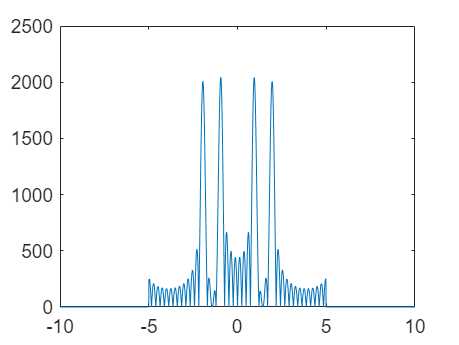

fl = length(fmixed);
gate = [zeros(1,pos),ones(1,fl-2*pos),zeros(1,pos)];
flited = Mixed .* gate;
plot(fmixed,abs(flited));
xlim([-10,10]);

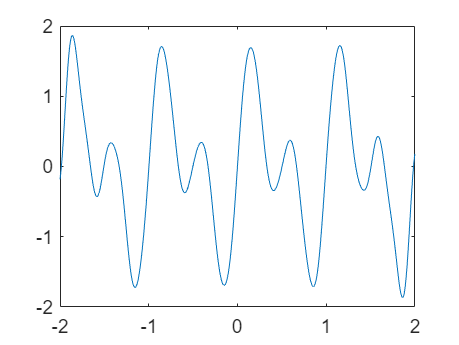


%截取
figure(5);
x_ifft = ifftshift(ifft(ifftshift(flited)));
x_ifft = x_ifft(51600:55730);
t_ifft = -2:4/4131:1.9999;
plot(t_ifft,real(x_ifft));
xlim([-2,2]);